# Mapa logistico

clc; clear; close all;

tic
%{

============== CÓDIGO ORIGINAL Y PROBLEMAS =====================

function S = logisticSequence(seed, alpha, N0, N)

x = seed;
S = zeros(1, N + N0); %Se crea un vector muy grande, 
                          con 1.000 valores más.
                          Solo se necesita un vector con N valores
                          pues se descartan los primeros N0

for k = 1:(N + N0) 
    x = alpha * x * (1 - x);
    S(k) = x; %Se guardan los primeros N0 valores...
end

% eliminar transitorio
S = S(N0+1:end); %Se borran los valores, luego de almacenar los 1000
 
end
%}



%================== SOLUCION MEJOR OPTIMIZADA ====================

function S = logisticSequence(seed, alpha, N0, N)

    x = seed;

    % Acá se elimina el transitorio directamente sin guardarlo,
    % solo sobreescribiendo el valor de x

    for k = 1:N0
        x = alpha * x * (1 - x);
    end

    % Aquí se generan los valores que si nos sirven, hasta N

    S = zeros(1, N);
    for k = 1:N
        x = alpha * x * (1 - x);
        S(k) = x;
    end
end



# Ordenamiento secuencia caótica


%{

============== CÓDIGO ORIGINAL Y PROBLEMAS =====================

function perm = getPermutationFromChaos(S)

[~, perm] = sort(S, 'ascend'); % 1. La secuencia caótica podría generar números
                                   repetidos

end

%}

%ES IMPORTANTE QUE S TENGA VALORES ENTRE 0 Y 1
%Con los valores de la semilla entre 0 y 1 y el valor de alpha
%entre (3.57 , 4] (donde garantiza que hay caos) hará que la generación
%de la secuencia esté siempre entre 0 y 1

function perm = getPermutationFromChaos(S)

% Ahora tiene un ordenamiento estricto, en caso de que haya dos números
% generados que sean iguales, se mantiene en orden de ascendencia

[~, perm] = sort(S, 'ascend', 'ComparisonMethod', 'auto');

% PREGUNTAR SI HACER UNA VALIDACIÓN DE QUE LOS VALORES DE LA SEMILLA
% Y DE EL VALOR DE ALPHA

end

# Permutacion intra bit



%MATLAB guardan los número en 64 bits, pero se muestran menos
%si se quiere imprimir los números utilizar "format long".

function [bp_perm, Gmask, perm] = intraBitPermutation(bp, seed)


%============================================================
%AGREGADO DE OPTIMIZACIÓN:

bp = logical(bp); %Los números se vuelven binario, 
                  %por lo que las operaciones de ahora en adelante se hacen
                  %8 veces más rápido
%============================================================

[filas, columnas] = size(bp);
N = filas * columnas;

% parámetros del paper
alpha = 3.99999;
N0 = 1000; % PREGUNTAR POR 10.000

% 1. secuencia caótica
S = logisticSequence(seed, alpha, N0, N);

% 2. obtener permutación
perm = getPermutationFromChaos(S);

% 3. aplicar permutación
vector = bp(:); % Se aplana la matriz para organizarlos
vector_perm = vector(perm);

bp_perm = reshape(vector_perm, filas, columnas);

% 4. calcular máscara G (XOR)
Gmask = xor(bp, bp_perm);

end

# Permutacion Interbit

function [bitplanes_out, order] = interBitPermutation(bitplanes, seed)

%[filas, columnas, numBits] = size(bitplanes); %No se usan las variables
% filas y columnas

%=============================================================
%AGREGADO DE OPTIMIZACIÓN:
bitplanes = logical(bitplanes); % Lo vuelve a 8bits

[~, ~, numBits] = size(bitplanes); %elimina las variables que no se usan

%=============================================================


% Parámetros del mapa logístico
alpha = 3.99999;
N0 = 1000;

% generar secuencia caótica
S = logisticSequence(seed, alpha, N0, numBits);

% obtener orden caótico de planos
%[~, order] = sort(S,'ascend'); %SE ELIMINA PARA GENERAR MEJOR "OS"

%=============================================================
%AGREGADO DE OPTIMIZACIÓN:

order = getPermutationFromChaos(S); %Genera el "OS" caótico

%=============================================================

bitplanes_out = bitplanes;

%pairs = []; % Ya no se necesitan pares

% aplicar XOR entre pares de planos


%{

%SE QUITA ESTE FOR

for k = 1:2:(numBits-1)
    
    b1 = order(k);
    b2 = order(k+1);
    
    bitplanes_out(:,:,b2) = xor(bitplanes_out(:,:,b2), bitplanes_out(:,:,b1));
    
    pairs = [pairs; b1 b2];
    
end
%}


for m = 2:numBits %inicia en la segunda y se opera con el anterior

        % Plano de control (el anterior en la secuencia OS)
        b_control = order(m-1); 


        % Plano objetivo (el actual en la secuencia OS)
        b_target = order(m);    
        
        % Aplicar compuerta XOR cuántica
        % Matriz(target) = Matriz(target) XOR Matriz(control)
        

        %Se hace una xor normal, se puede simular con compuertas xor
        %cúanticas, pero el rendimiento es terrible :(

        %Para una imagen de 256, de 8 capas, habría que simular aprox
        % 458.752 compuertas Xor, suponiendo que es solo gris.

        bitplanes_out(:,:,b_target) = xor(bitplanes_out(:,:,b_target), bitplanes_out(:,:,b_control));
end
end

# Compuertas not

%POR ESTO SE DEMORA TANTO EN GENERAR LA IMAGEN

%Se genera un doble loop que va fila por fila, pero MATLAB tiene otra
%función



%{

function qc = buildIntraBitCircuit(Gmask)

[filas, columnas] = size(Gmask);
N = filas * columnas;

gates = [];

index = 1;

for i = 1:filas
    for j = 1:columnas
        
        if Gmask(i,j) == 1
            gates = [gates; xGate(index)];
        end
        
        index = index + 1;
    end
end

qc = quantumCircuit(gates, Name="IntraBit");

end


%}


function qc = buildIntraBitCircuit(Gmask)

    % 1. Encontrar los índices (q-ubits) a modificar
    % El código original usaba un doble loop que avanzaba fila por fila.
    % MATLAB internamente trabaja columna por columna. 
    % Para obtener los mismos índices exactos sin usar 'for', transponemos 
    % la matriz (Gmask') y usamos find().
    % Esto nos da un vector con todas las posiciones que tienen un 1.

    targetQubits = find(Gmask');

    % 2. Construir el circuito (Vectorización)
    % Si la máscara está vacía (no hay unos), devolvemos circuito vacío


    if isempty(targetQubits)
        qc = quantumCircuit([], Name="IntraBit");
    else
        % La librería cuántica de MATLAB permite pasarle un vector de qubits
        % a la compuerta. En lugar de crear miles de compuertas una por una,
        % creamos una sola operación paralela en todos los qubits objetivo.
        gates = xGate(targetQubits);
        
        qc = quantumCircuit(gates, Name="IntraBit");
    end
end


# Difusion Caotica

function img_diff = chaoticDiffusion(img, seed)

    % 1. Extraer dimensiones
    [filas, columnas] = size(img);
    N = filas * columnas;

    % Parámetros estandarizados del paper
    alpha = 3.99999;
    N0 = 1000; 

    % 2. Generar secuencia caótica (S es 1 x N)
    S = logisticSequence(seed, alpha, N0, N);

    % 3. Convertir a llave K y OBLIGAR a que sea columna
    % Usar (:) asegura que, sin importar lo que pase, K será N x 1
    K_temp = uint8(floor(S * 256));
    K = K_temp(:); 

    % Vectorizar la imagen original (OBLIGAR a que sea columna)
    P = img(:);

    % 4. OPTIMIZACIÓN MÁXIMA
    % Como P y K ahora son ESTRICTAMENTE vectores N x 1, 
    % MATLAB hará un XOR elemento por elemento (1D), no una matriz 2D.
    V = bitxor(P, K);

    % Preasignar memoria
    C = zeros(N, 1, 'uint8');

    % 5. Difusión en cascada 
    C(1) = V(1);
    
    for i = 2:N
        C(i) = bitxor(V(i), C(i-1));
    end

    % 6. Reconstruir la imagen
    img_diff = reshape(C, filas, columnas);

end

# **Lectura de imagen y separación de capas RGB**

%1. Leer la imagen
img = imread('\Peppers.jpg')

img = 512×512×3 uint8 array
img(:,:,1) =

   103   140   147   160   160   141   128   138   138   138   169   170   173   187   174   185   193   207   202   199   211   205   205   201   213   205   204   205   201   205   200   209   204   205   206   206   207   209   206   207   214   216   209   205   208   205   208   212   208   209   207   208   208   208   205   207   213   203   205   197   201   203   208   208   206   207   208   201   212   205   202   206   204   204   213   210   205   208   205   211   211   204   206   205   206   208   208   212   210   211   211   202   199   201   204   214   202   205   209   206   211   212   208   201   210   200   213   200   196   207   196   207   196   203   196   202   198   194   201   197   200   193   194   195   195   194   196   195   193   191   190   185   183   182   182   182   181   182   183   185   185   186   187   190   186   186   185   185   186   185   186   189   194   191   193   195   194   193   194   1

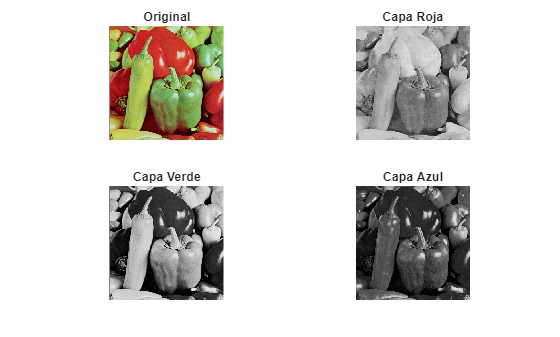


% 2. Separar en capas R, G, B
rojo  = img(:,:,1);
verde = img(:,:,2);
azul  = img(:,:,3);

% 3. Visualizar las capas
figure;
subplot(2,2,1); imshow(img); title('Original')
subplot(2,2,2); imshow(rojo); title('Capa Roja')
subplot(2,2,3); imshow(verde); title('Capa Verde')
subplot(2,2,4); imshow(azul); title('Capa Azul')

# Encriptacion Imagen creada 

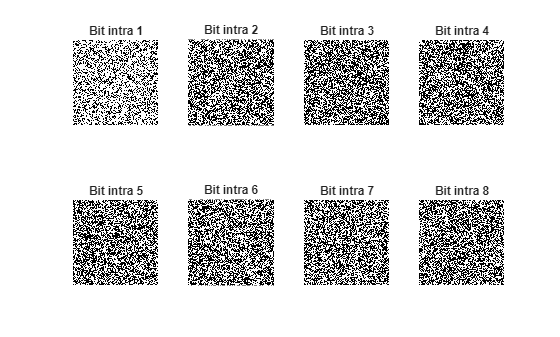

%{



%% Leer imagen
%%img = imread('C:\Users\marlo\OneDrive\Documentos\Mis documentos\UD\COMPLEX\pepers.jpg');
img = uint8([ ...
 30  45  60  75  90 105 120 135 150 165 180 195 210 195 180 165;
 45  70  90 110 130 150 170 190 210 200 190 180 170 160 150 140;
 60  90 130 170 200 220 230 240 250 240 230 220 210 200 180 160;
 75 110 170 210 240 250 240 230 220 210 200 190 180 170 160 150;
 90 130 200 240 250 240 220 200 200 220 240 250 230 210 190 170;
105 150 220 250 240 200  30  40  40  30 200 240 250 230 210 190;
120 170 230 240 220  40  10  15  15  10  40 220 240 230 210 200;
135 190 240 230 200  40  15  10  10  15  40 200 230 240 220 210;
150 210 250 220 200  40  15  10  10  15  40 200 220 250 230 220;
165 200 240 210 220  30  10  15  15  10  30 220 210 240 230 220;
180 190 230 200 240 200  40  30  30  40 200 240 200 230 220 210;
195 180 220 190 250 240 220 200 200 220 240 250 210 200 190 180;
210 170 210 180 230 250 240 230 220 230 240 250 220 210 200 190;
195 160 200 170 210 230 240 250 240 230 220 210 200 190 180 170;
180 150 180 160 190 210 230 240 250 240 230 220 210 200 190 180;
165 140 160 150 170 190 210 220 230 240 250 240 230 220 210 200
]);

rojo = img(:,:,1);

subplot(1,2,1); imshow(img);   title('Original');
%}
%% Obtener planos de bits

[filas, columnas] = size(rojo);
rojo_bin = zeros(filas, columnas, 8);

for k = 1:8
    rojo_bin(:,:,k) = bitget(rojo, 9-k);
end

%% ===== PERMUTACIÓN INTRA BIT =====

seeds = [0.5 0.52 0.53 0.6 0.37 0.46 0.38 0.61];

rojo_perm = zeros(size(rojo_bin));
circuits = cell(1,8);

for k = 1:8
    
    bp = rojo_bin(:,:,k);
    
    [bp_perm, Gmask, perm] = intraBitPermutation(bp, seeds(k));
    
    rojo_perm(:,:,k) = bp_perm;
    
    % circuito cuántico
    circuits{k} = buildIntraBitCircuit(Gmask);
    
end

%% Visualizar planos permutados

figure;
for k = 1:8
    subplot(2,4,k)
    imshow(rojo_perm(:,:,k))
    title(['Bit intra ', num2str(k)])
end

## Mostrar un circuito de ejemplo

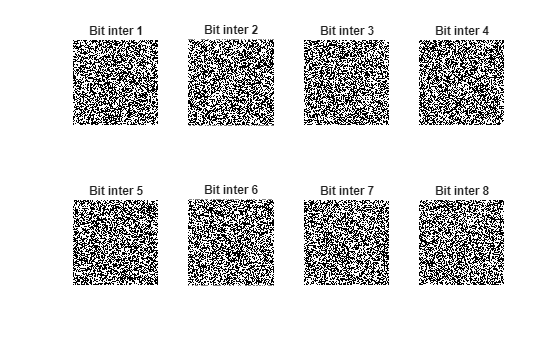


%{
figure('Position', [100, 100, 2400, 1600]);  % [x, y, ancho, alto]
plot(circuits{1});
title('Circuito intra-bit plano 1');
%}
%% ===== PERMUTACIÓN INTER BIT =====

seed_inter = 0.73;

[rojo_inter, pairs] = interBitPermutation(rojo_perm, seed_inter);

%% Visualizar planos después de inter-bit

figure;

for k = 1:8
    
    subplot(2,4,k)
    imshow(rojo_inter(:,:,k))
    title(['Bit inter ', num2str(k)])
    
end

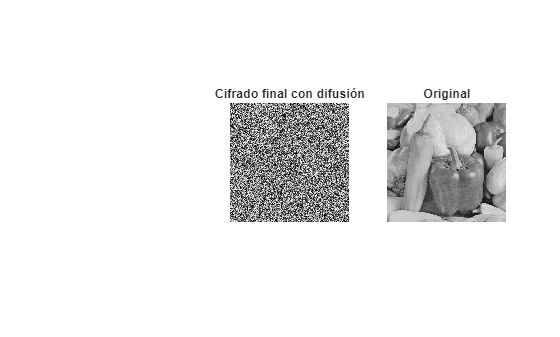

%% ===== RECONSTRUCCIÓN DE LA IMAGEN =====
% El código antiguo usaba sumas y multiplicaciones por potencias de 2
% que generan errores de tipo (double vs uint8).

% MATLAB tiene una función  'bitset' para meter bits 
% directamente dentro de un número.

% 1. Preasignamos la matriz en uint8
img_cifrada = zeros(filas, columnas, 'uint8');

% 2. Insertamos cada plano lógico en su posición correspondiente
for k = 1:8
    % OJO: El plano 1 es el bit más significativo (posición 8 en bitset)
    % El plano 8 es el bit menos significativo (posición 1 en bitset)
    posicion_bit = 9 - k; 
    
    img_cifrada = bitset(img_cifrada, posicion_bit, rojo_inter(:,:,k));
end

%% ===== DIFUSIÓN CAÓTICA =====
seed_diff = 0.81;
img_diff1 = chaoticDiffusion(img_cifrada, seed_diff);
figure

subplot(1,3,2)
imshow(img_diff1)
title('Cifrado final con difusión')
subplot(1,3,3)
imshow(rojo)
title('Original')

# Difusion inversa

%{

function img = inverseChaoticDiffusion(img_diff, seed)

[filas, columnas] = size(img_diff);
N = filas * columnas;

alpha = 3.99999;
N0 = 1000;

S = logisticSequence(seed, alpha, N0, N);

K = uint8(floor(S * 256));

C = img_diff(:);
P = zeros(N,1,'uint8');

P(1) = bitxor(C(1), K(1));

for i = 2:N
    
    P(i) = bitxor(bitxor(C(i), K(i)), C(i-1));
    
end

img = reshape(P, filas, columnas);

end
%}

% ---- CÓDIGO ORIGINAL (Lento por el for loop) ----
% function img = inverseChaoticDiffusion(img_diff, seed)
% [filas, columnas] = size(img_diff);
% N = filas * columnas;
% alpha = 3.99999;
% N0 = 1000;
% S = logisticSequence(seed, alpha, N0, N);
% K = uint8(floor(S * 256));
% C = img_diff(:);
% P = zeros(N,1,'uint8');
% P(1) = bitxor(C(1), K(1));
% for i = 2:N
%     P(i) = bitxor(bitxor(C(i), K(i)), C(i-1));
% end
% img = reshape(P, filas, columnas);
% end
% ---- FIN CÓDIGO ORIGINAL ----

function img = inverseChaoticDiffusion(img_diff, seed)

    % 1. Extraer dimensiones
    [filas, columnas] = size(img_diff);
    N = filas * columnas;

    % Parámetros estandarizados
    alpha = 3.99999;
    N0 = 1000; % Aseguramos el mismo N0 que al encriptar

    % 2. Re-generar la misma llave K y hacerla vector columna
    S = logisticSequence(seed, alpha, N0, N);
    K_temp = uint8(floor(S * 256));
    K = K_temp(:); 

    % 3. Vectorizar la imagen encriptada (columna)
    C = img_diff(:);

    % Preasignar memoria para la imagen recuperada
    P = zeros(N, 1, 'uint8');

    % 4. MAGIA DE VECTORIZACIÓN: Eliminar el For Loop
    % Ecuación: P(i) = C(i) XOR K(i) XOR C(i-1)
    
    % Primer elemento (caso especial, no tiene C(i-1))
    P(1) = bitxor(C(1), K(1));

    % Para todos los demás elementos del 2 al N de un solo golpe:
    % C(2:end) es el C actual. 
    % C(1:end-1) es el C anterior.
    % Hacemos XOR entre los C actuales y los anteriores.
    temp_xor = bitxor(C(2:end), C(1:end-1));
    
    % Luego cruzamos eso con las llaves K del 2 al N.
    P(2:N) = bitxor(temp_xor, K(2:end));

    % 5. Reconstruir la imagen
    img = reshape(P, filas, columnas);

end

# Inversa interbit

%{

function bitplanes = inverseInterBitPermutation(bitplanes, pairs)

for k = size(pairs,1):-1:1
    
    b1 = pairs(k,1);
    b2 = pairs(k,2);
    
    bitplanes(:,:,b2) = xor(bitplanes(:,:,b2), bitplanes(:,:,b1));
    
end

end
%}

function bitplanes = inverseInterBitPermutation(bitplanes, order)

    % 1. Optimización: Obligamos a que bitplanes sea de tipo 'logical' 
    % para que el XOR sea rápido.
    bitplanes = logical(bitplanes);
    numBits = length(order); % Debería ser 8 (la cantidad de planos)

    % 2. Reversibilidad (Deshacer la Cascada)
    % En la encriptación, el loop iba de 2 hacia numBits (arriba hacia abajo).
    % Para deshacer un circuito cuántico en serie, debemos aplicar 
    % exactamente las mismas compuertas, pero de abajo hacia arriba.
    % Por eso empezamos en numBits y bajamos (-1) hasta 2.
    for m = numBits:-1:2
        % Plano de control (el mismo que se usó al encriptar)
        b_control = order(m-1); 
        % Plano objetivo (el mismo que fue modificado al encriptar)
        b_target = order(m);    
        
        % Aplicar el XOR (CNOT auto-inverso)
        bitplanes(:,:,b_target) = xor(...
            bitplanes(:,:,b_target), ...
            bitplanes(:,:,b_control) ...
        );
    end
% bitplanes = double(bitplanes);

end

# Inversa intra bit

function bp = inverseIntraBitPermutation(bp_perm, perm)

[filas, columnas] = size(bp_perm);

vector = bp_perm(:);

invperm(perm) = 1:length(perm);

vector_original = vector(invperm);

bp = reshape(vector_original, filas, columnas);

end

# Desencriptacion

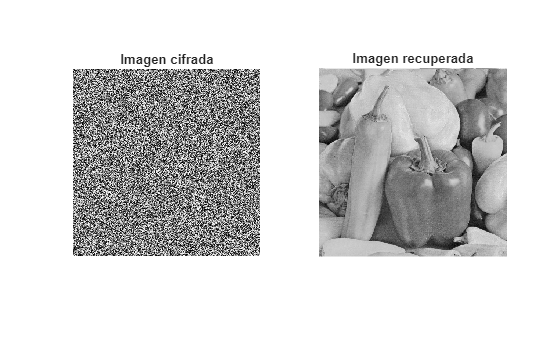

%% cargar imagen cifrada
img_diff = img_diff1;

[filas,columnas] = size(img_diff);

%% ===== DESHACER DIFUSIÓN =====

seed_diff = 0.81;

img_perm = inverseChaoticDiffusion(img_diff, seed_diff);

%% ===== SEPARAR PLANOS DE BITS =====

bitplanes = zeros(filas,columnas,8);

for k=1:8
    
    bitplanes(:,:,k) = bitget(img_perm,9-k);
    
end

%% ===== DESHACER INTER-BIT =====

bitplanes = inverseInterBitPermutation(bitplanes, pairs);

%% ===== DESHACER INTRA-BIT =====

seeds = [0.5 0.52 0.53 0.6 0.37 0.46 0.38 0.61];

for k=1:8
    
    S = logisticSequence(seeds(k),3.99999,1000,filas*columnas);
    
    [~,perm] = sort(S,'ascend');
    
    bitplanes(:,:,k) = inverseIntraBitPermutation(bitplanes(:,:,k),perm);
    
end

%% ===== RECONSTRUIR IMAGEN =====

img_original = zeros(filas,columnas,'uint8');

for k=1:8
    
    img_original = img_original + uint8(bitplanes(:,:,k))*2^(8-k);
    
end

%% mostrar resultado

figure

subplot(1,2,1)
imshow(img_diff)
title("Imagen cifrada")

subplot(1,2,2)
imshow(img_original)
title("Imagen recuperada")


tiempofinal = toc;
fprintf('El tiempo fue de: %.4f ', tiempofinal)

El tiempo fue de: 20.5425 